# Derivatives

How much time do you have to drink your coffee before it becomes too cold? How far will a ball travel before it hits the ground? Will my couch fit through the hallway into my apartment? Many every-day interactions can be described by functions, and these functions can be analyzed by studying their rates of change. 

  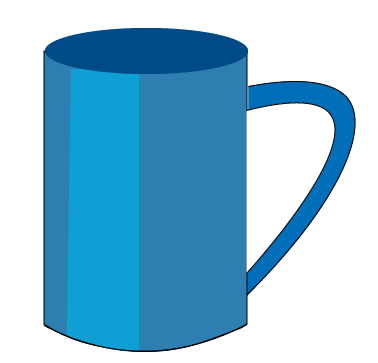               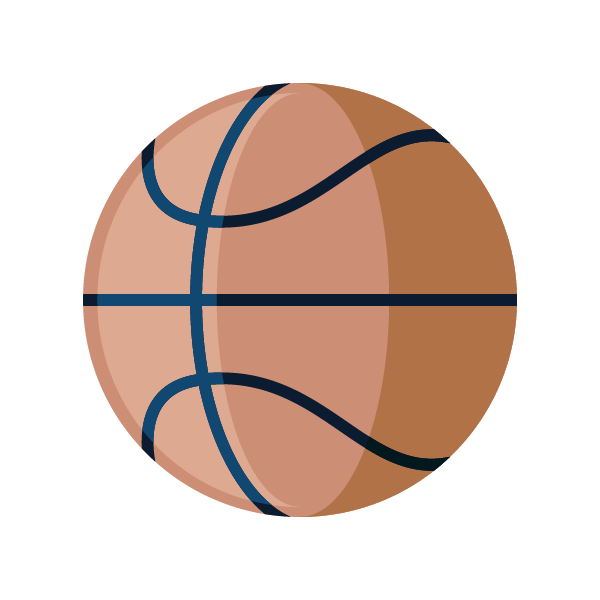                  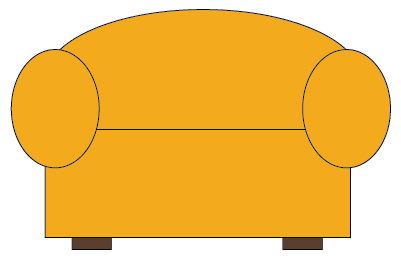

Derivatives allow us to answer these questions by computing rates of change for a given function. 

**Before you get started:**

 This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor window.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://www.mathworks.com/learn/tutorials/matlab-onramp.html), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## Definition of the Derivative

The derivative of a function tracks the rate of change of that function at each point in its domain. 

#### Motivating Example: Cooling Coffee

Consider the function $T(t)$ that tracks the temperature, in degrees Celsius, of a cup of coffee as a function of time, in minutes. If the coffee is poured out of a temperature-controlled carafe held at $95^{\circ}$C at $t=5$ minutes, a representative cooling curve is presented below. The rate of change of $T(t)$ with respect to time $t$ in this scenario is the rate at which the coffee is cooling, with units of degrees Celsius per minute. Calculus provides tools that can determine the rate of change at each point of this function. 

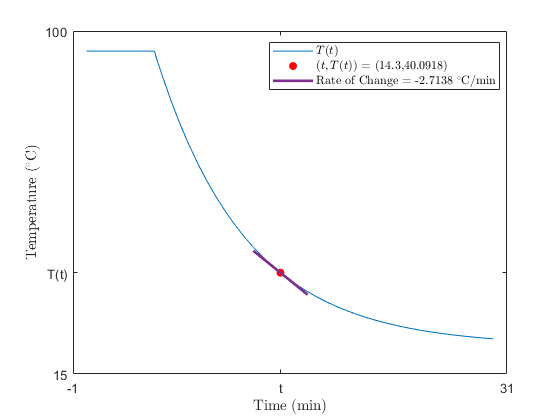

x1 = 14.3;
coffeeExample(x1)

#### Motivating Example: Basketball

The height of a basketball $H$, in meters, as a function of the time $t$, in seconds has a derivative that tracks the rate of change of height with respect to time in meters per second. The derivative of a position function with respect to time is a velocity function.

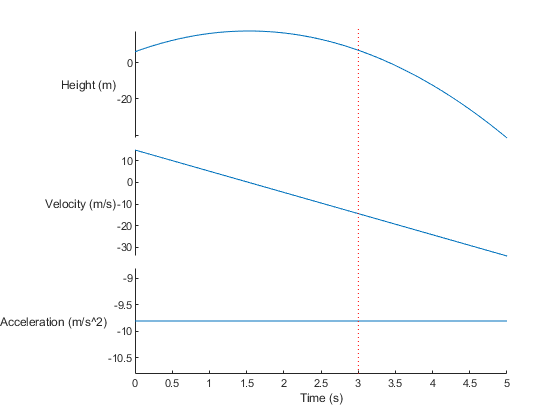

xpt = 3;
basketballExample(xpt)

#### Motivating Example: Moving a couch

Consider moving a couch into a new apartment. It may be necessary to maneuver the couch around a corner, but couches are not flexible. Calculus offers tools to determine whether a one-dimensional couch will fit around a corner by providing a method that will locate the minimal value of the `maxCouchLength` over all paths around this curve. Similar methods could be employed for a more realistic three dimensional couch.

$$dL(y) = \frac{2\,y-\frac{2\,{\left(3\,y-30\right)}^{2}}{{\left(y-9\right)}^{3}}+\frac{18\,y-180}{{\left(y-9\right)}^{2}}-20}{2\,\sqrt{\frac{{\left(3\,y-30\right)}^{2}}{{\left(y-9\right)}^{2}}+{\left(y-10\right)}^{2}}}$$

what = 8.0000

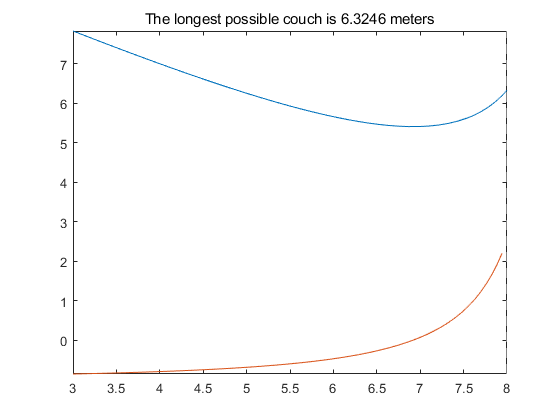

minMaxCouchLength = couchExample([3 9]);

### Limit Definition of the Derivative

More formally, the derivative of a function $y=f(x)$ is defined as the limit of the slopes of secant lines between the points $(x,f(x))$ and $(x+h,f(x+h))$:


$$f'(x) = \lim_{h \rightarrow0} \enspace\frac{f(x+h) - f(x)}{h}$$
 

Let $h = \Delta x = x_2-x_1$:

       
$$\frac{df}{dx} = \lim_{\Delta x \to 0} \frac{f(x+\Delta x) - f(x)}{\Delta x}$$


Let $\Delta f = f(x_2)-f(x_1) = y_2 - y_1$:

       
$$=\lim_{\Delta x \to 0} \frac{\Delta f}{\Delta x}~~~~~~~~~~$$


   
$$= \lim_{(x_2-x_1) \to 0} ~\frac{y_2 - y_1}{x_2-x_1}$$


### Derivatives as Limits of Secant Lines

  **Try. **

First, use the default function to set up a graphical representation of the limit definition. Then try a few more functions of your choice.

syms x f(x)
f(x) =  x^3

$$f(x) = x^{3}$$

  **Pro-tip**. MATLAB syntax is `3*x^2` for $3x^2$ or `exp(2x)` for $e^{2x}$. For more detail, check out the Help Center documentation for [mathematical functions](https://www.mathworks.com/help/matlab/referencelist.html?type=function&listtype=cat&category=mathematics) or the [Basic Functions Reference](https://www.mathworks.com/content/dam/mathworks/fact-sheet/matlab-basic-functions-reference.pdf).

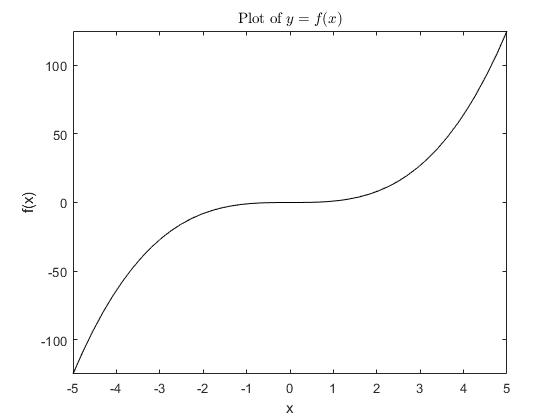

 
clf
fplot(f(x),"k")
xlabel("x")
ylabel("f(x)")
title("Plot of $y = f(x)$","Interpreter","latex")

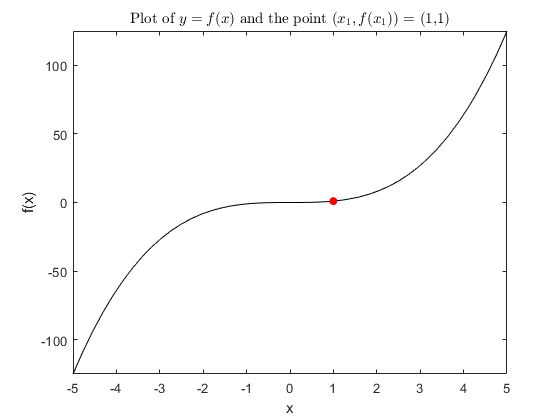

x1 = 1;
 
fplot(f(x), "k")
hold on
scatter(x1,f(x1),"r","Filled")
hold off
xlabel("x")
ylabel("f(x)")
title("Plot of $y = f(x)$ and the point $(x_1, f(x_1))$ = (" + x1 + "," + double(f(x1)) + ")","Interpreter","latex")

x2 = -4;
 
h = x2-x1;
disp("h = " + h)

h = -5


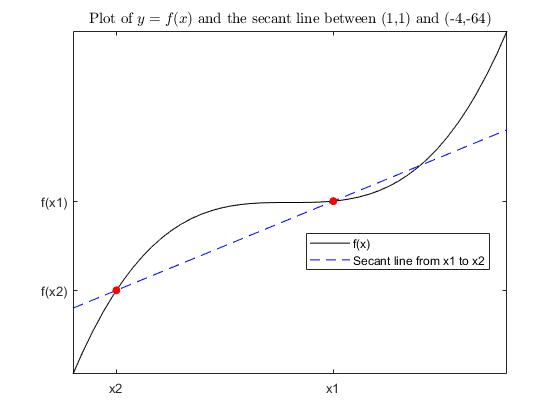

fh = @(x) f(x);
out = graphSecant(fh,x1,x2,"f");

if out
    warning("There is no secant line through a single point. Graphing the tangent line.")
end

  **Try **

Investigate what happens for different values of `x1` and `x2` and for different functions `f(x)`.  

 **Reflect**

- What do you notice about the slope of the secant line as you change `x2`?

- What happens when you set `x2` equal to `x1`?

- Can you find values for `x1` and `x2` where the secant line has a positive slope? Or negative slope? Or zero slope? 

- Do your answers to Question 3 change if you start with a different function `f(x)`?

## Computing Derivatives at a Point

Now let's try evaluating the definition of the derivative at different points. Notice that when the derivative is positive, the function is increasing (and vice versa). The function we are exploring here is $y = 6 + \cos(x) - \frac{32}{5}e^{-x/5}$ over a range from $x=0$ to $x=25$. 

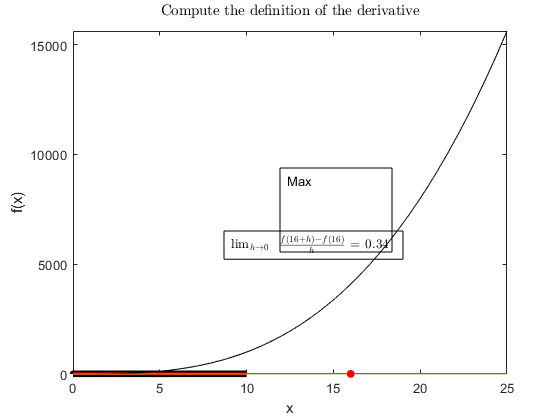

xPosn = 16;
exampleFunction(xPosn);

 **Reflect**

- What do you notice about the derivative near the top of a peak? What about near the bottom of a valley? 

- Can you calculate the derivative of this function from its limit definition? Why or why not?

## **Graphical Derivatives**

Surprisingly often, it is sufficient to know the sign (positive, negative, or zero) of a derivative. A positive derivative means the function is increasing in value from left to right. A negative value means the function is decreasing in value from left to right. And a zero derivative means the function is constant, neither increasing nor decreasing, in value.

syms x
g(x) =  exp(x)*cos(x)+x^2
xa = -3;
 
fplot(g,"k");
hold on
scatter(xa, g(xa),"r","filled")
hold off
title("Plot of $y = g(x)$ and the point $(x_1, g(x_1))$ = (" + xa + "," + double(g(xa)) + ")","Interpreter","latex")
xlabel("$x$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")

** Exercise**. Determine the sign of the derivative at the point you have selected:

slope = "positive"
 
if ~exist("xa","var")
    xa = 3;
end
if ~exist("g","var")
    syms x
    g(x) = exp(x)*cos(x)+x^2;
end
checkSlope(slope,@(x) g(x),xa,"g");

 **Reflect**

- How easy is it to find points where the derivative is zero? Do they exist on your graph? Why or why not?

- What does knowing the sign of the derivative tell you about your function?

- Using + for regions with a positive derivative, - for regions with a negative derivative, and 0 for regions where the derivative is zero, can you sketch two or more functions with derivatives that fit different patterns? How about + everywhere? Or -0+? Or +0-0+? Perhaps -0-? 

- Can you sketch a function with a derivative that is -+ and never 0? Why or why not? 

#### Derivative as an Operator

The derivative can be thought of as an operator $\frac{d}{dx}$ which acts on one function $f(x)
$ using it to produce a new function $\frac{df}{dx}$ that tracks the rate of change of the original function at each point. Alternatively, you can think of the derivative as a black box which accepts a function as input and returns a new, but related, function as output, similar to some visualizations of functions themselves:

For a function, the input $x$ is transformed to an output $f(x)$:

For a derivative, the input $f(x)$ is transformed to an output $\frac{df}{dx}$ which can also be written as $f'(x)$:

 

## Notes on Notation

You may see the derivative of a function represented using different notation. 

Notation:                        Read As:

         $f'(x)$                     "eff prime of ex", 

           $\frac{df}{dx}$                         "dee eff dee ex",

             $\frac{d}{dx}[f(x)]$            "dee dee ex of eff of ex",

While they may appear different, all of these notations mean the same thing: the derivative of a function $f(x)$ with respect to the variable $x$. 

While the function f and x were chosen for this example, you can extend this notation to any function and variable! For example, the derivative of the function g with respect to the variable z (in its notations corresponding to above) would look like:


$$g'(z), \enspace \frac{dg}{dz},\enspace\frac{d}{dz}[g(z)]$$


There is a subtle difference in notation between $f'(x), \enspace \frac{df}{dx} \enspace$ and  $\frac{d}{dx}[f(x)]$. The former describe functions which are the result of applying the derivative operator to a function. The notation $f'(x)$ is called "prime notation" and is primarily used as a shorthand when there is only one independent variable and especially when the derivative is going to be evaluated at specific points, such as $f'(a)$ to describe the slope of the function $f(x)$ at the point $x=a$. The latter references the act of taking a derivative of a function. In this sense, the latter notation refers to the derivative as an "operator" where it "operates/acts" on the original function. 

## Helper Functions

  If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor window.

function coffeeExample(x1)
% This example creates the graph of the cooling coffee example
    syms t
    T(t) = piecewise(t<5,95,73*exp(-.15*(t-5))+22); 
    y1 = double(T(x1));
    [m,linApprox] = getLinApprox(T,t,x1);
    fplot(T,[0 30]);
    hold on
    scatter(x1,y1,'r','filled')
    fplot(linApprox,[x1 - 2,x1 + 2],"Color",[0.4940 0.1840 0.5560],"LineWidth",2); % Purple
    hold off
    ylim([15 100])
    xlim([-1 31])
    xlabel("Time (min)","Interpreter","latex")
    ylabel("Temperature ($^{\circ}$C)","Interpreter","latex")
    xticks([-1 x1 31]);
    yticks([15 y1 100]);
    xticklabels(["-1" "t" "31"])
    yticklabels(["15" "T(t)" "100"])
    legend(["$T(t)$" "$(t,T(t))$ = ("+x1+","+y1+")" "Rate of Change = "+m+" $^{\circ}$C/min"],"Location","best","Interpreter","latex")
end
    
function [m,linApprox] = getLinApprox(y,x,h)
    % getLinApprox creates a tangent line function to y(x) at the point x=h
    %
    % getLinApprox requires four arguments
    %   y a symbolic function
    %   x the independent variable
    %   h the point of tangency
    % getLinApprox returns two values
    %   m is the slope as a double
    %   linApprox is the tangent line to y(x) at x=h as a symfun
    dy = diff(y,x);
    m = subs(dy,x,h);
    linApprox = m*x + (subs(y,x,h) - m*h);
    m = double(m);
end

function basketballExample(xpt)
    ypt = [6-9.81/2*xpt^2+25*xpt -9.81*xpt+15 -9.81];
    tVals = 0:.01:5;
    hVals = 6-9.81/2*tVals.*tVals+15*tVals;
    vVals = -9.81*tVals+15;
    aVals = -9.81*ones(size(tVals));
    yVals = [hVals' vVals' aVals'];
    s = stackedplot(tVals,yVals,"DisplayLabels",["Height (m)" "Velocity (m/s)" "Acceleration (m/s^2)"]);
    xlabel("Time (s)")
    xloc = .9061-.1331*(5-xpt);
    fig = gcf;
    aHandle = annotation("line",[xloc xloc],[.1100 .9350],"Color","r","LineStyle",":");
end

function shortest = couchExample(corner)
% couchExample animates the minimization problem of a length passing around
% a corner
%
% couchExample takes one argument
%    corner=[a,b] with 0 < a,b < 10 locating a corner
% couchExample returns one value
%    shortest is the minimal maximal length of a straight line from one hallway
%    wall to the other
    clf
    plot([0 0 10],[0 10 10],"k-","LineWidth",5)
    hold on
    plot([corner(1) corner(1) 10],[0 corner(2) corner(2)],"k-","LineWidth",5)
    title("A Hallway and (theoretical) Couch")
    couch = plot([0 10/3],[0 10],"r-","LineWidth",2);
    maxCouchLength = sqrt((10/3)^2+(10-0)^2);
    noteMaxLength = annotation("textbox",[.45,.4,.4,.2],"String","Maximum couch length = "+maxCouchLength,"EdgeColor","w");
    pause(0)
    for cy=0:.1:8.9
        m = (corner(2)-cy)/corner(1);
        xLargest = min([(10-cy)/m 10]);
        if xLargest == 10
            yLargest = m*10+cy;
        else
            yLargest = 10;
        end
        couch.XData = [0 xLargest];
        couch.YData = [cy yLargest];
        length = sqrt(((10-cy)/m)^2+(10-cy)^2);
        noteMaxLength.String = "Maximum couch length = "+length;
        pause(0)
    end
    hold off
    couch.XData = [0 10];
    couch.YData = [corner(2) corner(2)];
    noteMaxLength.String = "Maximum couch length = Infinite";
    pause(0)
    syms y
    L(y) = sqrt(((corner(1)*(10-y))/(corner(2)-y))^2+(10-y)^2);
    fplot(L,[3 8])
    hold on
    dL = diff(L,y)
    fplot(dL,[3 8])
    minY = fzero(dL,7);
    hold off
    shortest = double(L(minY));
    subtitle("The longest possible couch is "+shortest+" meters")
end

function out = graphSecant(fh,x1,x2,fstr)
    % graphSecant plots a curve y=fh(x) and a secant line between 
    % two distinct points (x1, fh(x1)) and (x2, fh(x2)) or the tangent
    % line to fh(x) at x=x1. It returns a logical value.
    %
    % graphSecant requires four arguments
    %        fh a function handle
    %        x1   a number 
    %        x2   a number
    %        fstr a function string, e.g., "f"
    % graphSecant returns one value
    %        out is a logical that is 1 if x1=x2 and 0 if x1 ~= x2
    out = x1==x2;
    syms x;
    f(x) = fh(x);
    if x2 ~= x1
            secant(x) = f(x1) + (f(x2)-f(x1))/(x2-x1)*(x-x1);
        else
            df = diff(f);
            secant(x) = f(x1) + df(x1)*(x-x1);
    end
    fplot(f(x),"k")
    hold on
    fplot(secant(x),"b--")
    scatter(x1,f(x1),"r","Filled")
    scatter(x2,f(x2),"r","Filled")
    ax = gca;
    noTickOverlaps(x1,x2,"x1","x2",ax,"x","horiz")
    y2 = double(simplify(f(x2)));
    y1 = double(simplify(f(x1)));
    noTickOverlaps(y1,y2,fstr+"(x1)",fstr+"(x2)",ax,"y","vert")
    if x1 == x2
            legend([fstr+"(x)","Tangent line at x1"],"Location","best")
        else
            legend([fstr+"(x)","Secant line from x1 to x2"],"Location"," best")
    end
    hold off
    formatStr = "$y = %s(x)$";
    fStringL = compose(formatStr,fstr);
    if out
        title("Plot of " + fStringL + " and the tangent line through (" + x1 + "," + double(f(x1)) + ")","Interpreter","latex")
    else
        title("Plot of " + fStringL + " and the secant line between (" + x1 + "," + double(f(x1)) + ") and (" + x2 + "," + double(f(x2)) + ")","Interpreter","latex")
    end
end

function noTickOverlaps(y1,y2,str1,str2,ax,var,opt)
% y1, y2 are numbers, str1 and str2 are strings that label points y1 and
% y2, ax is a handle to a figure axis, and var is the variable of interest
% and opt is either "vert" or "horiz" to choose how to display overlapping
% labels
switch var
    case "x"
        valMinMax = ax.XLim;
    case "y"
        valMinMax = ax.YLim;
    case "z"
        valMinMax = ax.ZLim;
end

varScale = valMinMax(2)-valMinMax(1);

    if y1 == y2
        tickLocations = y1;
        formatStr = "%s = %s";
        labelStr = compose(formatStr,str1,str2);
        tickNames = [labelStr];
    elseif 0< y2-y1 && (y2-y1)/varScale < .03
        tickLocations = [y1 y2];
        if opt == "vert"
            tickNames = createStackedLabel(str2,str1);
        elseif opt == "horiz"
            tickNames = [str1+str2 " "];
        end
    elseif 0 < y1-y2 && (y1-y2)/varScale < .03
        tickLocations = [y2 y1];
        if opt == "vert"
            tickNames = createStackedLabel(str1,str2);
        elseif opt == "horiz"
            tickNames = [str2+str1 " "];
        end            
    elseif y1 < y2
        tickLocations = [y1 y2];
        tickNames = [str1 str2];
    else
        tickLocations = [y2 y1];
        tickNames = [str2 str1];
    end
switch var
    case "x"
        ax.XTick = tickLocations;
        ax.XTickLabel = tickNames;
    case "y"
        ax.YTick = tickLocations;
        ax.YTickLabel = tickNames;
    case "z"
        ax.ZTick = tickLocations;
        ax.ZTickLabel = tickNames;
end
end

function strOut = createStackedLabel(top,bot)
    row1 = [" " top];
    row2 = [" " bot];
    ylabelArray = [row1; row2];
    ylabelArray = strjust(pad(ylabelArray,"left"));
    strOut = sprintf("%s\\newline%s\n",ylabelArray{:});    
end

function exampleFunction(xPosn)
    syms y x;
    y = 6 + cos(x) - 32/5 * exp(-x/5);
    dy = diff(y);
    dyVal = subs(dy,x,xPosn);
    yVal = subs(y,x,xPosn);
    fplot(y)
    hold on
    xlim([0 25])
    scatter(xPosn,yVal,"red","filled")
    str = sprintf("$\\lim_{h \\rightarrow 0} \\enspace\\frac{f(%d+h) - f(%d)}{h}$ = %.2f",xPosn,xPosn,dyVal);
    annotation("textbox",[.4 .35 .1 .1],"String",str,"FitBoxToText","on","Interpreter","latex");
    hold off
    title("Compute the definition of the derivative")
end

function checkSlope(slopeGuess,gh,xa,gstr)
% checkSlope determines whether the string slopeGuess matches the actual
% slope of the function defined by the handle gh at the point xa. Then it
% plots the function and the tangent line at x=xa. 
%
%     slopeGuess is a string that is "positive", "negative" or "zero"
%     gh is a function handle
%     xa is a number
%     gstr is a string naming the function
    syms x;
    g(x) = gh(x);
    dg = diff(g,x);
    slope = double(dg(xa));
    if slope > 0
            correctSlope = "positive";
        elseif slope < 0 
            correctSlope = "negative";
        else
            correctSlope = "zero";
        end
        if (correctSlope == slopeGuess)
                disp("Correct. The slope at x=" + xa + " is " + slopeGuess + ".")
        elseif abs(slope)<.1 && abs(slope)>0
            disp("This might be frustrating, but the slope is not identically zero here. In fact, it is " + slope + " which is " + correctSlope + ".")
        else
            disp("Incorrect. The slope at x=" + xa + " is " + slope + " which is " + correctSlope + ".")
    end
    out = graphSecant(gh,xa,xa,"g");
end